# DATOS PISTA

logitudPista=3020;
anchuraPista=30;
%   DATOS SUPERFICIE DE TRANSICION
FranjaAnchura=150;
FranjaLongitud=60;
pendienteTransicion=0.143;
altura=45;
%  DATOS DESPEGUE
LogitudBordeInteriorDespegue=180;
DivergenciaDespegue=0.125;
logitudTotal=1500;
pendienteDespegue=0.02;
%   DATOS APROX
LogitudBordeInteriorAprox=300;
DivergenciaAprox=0.15;
LongitudPrimeraSeccion=3000;
pendienteAproximacion=0.02;

LongitudSegundaSeccion=3600;
pendienteAproximacion2=0.025;

LongitudTerceraSeccion=8600;


## Creamos figura pista

XXpista = [0,0,0,0,logitudPista,logitudPista,logitudPista,logitudPista]';
YYpista = [anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2,anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2]';
ZZpista = [0,1,0,1,0,1,0,1]';
Figurapista = alphaShape(XXpista,YYpista,ZZpista); %cramos la figura



% estas son las aristas de nuestro volumen
XXaprox = [-(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud),-FranjaLongitud,-FranjaLongitud,...
    -(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud)]'

XXaprox =        -3060
       -3060
         -60
         -60
       -3060
       -3060


YYaprox = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,-(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion),...
    -FranjaAnchura,FranjaAnchura,FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion)]'

YYaprox =    600
  -600
  -150
   150
   600
  -600


ZZaprox = [0,0,0,0,pendienteAproximacion*LongitudPrimeraSeccion,pendienteAproximacion*LongitudPrimeraSeccion]'

ZZaprox =      0
     0
     0
     0
    60
    60



FiguraAprox = alphaShape(XXaprox,YYaprox,ZZaprox); %cramos la figura


%% sdjfghklasdfhlkasdhjfdas

XXaprox2 = [-(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud),...
    -(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud)...
    -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),...
    -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion)]'

XXaprox2 =        -3060
       -3060
       -3060
       -3060
       -6660
       -6660
       -6660
       -6660



YYaprox2 = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,-(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion),...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion)...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion)]'

YYaprox2 =          600
        -600
         600
        -600
        1140
       -1140
        1140
       -1140



ZZaprox2 = [0,0,pendienteAproximacion*LongitudPrimeraSeccion,pendienteAproximacion*LongitudPrimeraSeccion...  
    0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
    pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion]'

ZZaprox2 =      0
     0
    60
    60
     0
     0
   150
   150



FiguraAprox2 = alphaShape(XXaprox2,YYaprox2,ZZaprox2); %cramos la figura


## aprox 3

XXaprox3 = [-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion)...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion)]'

XXaprox3 =        -6660
       -6660
       -6660
       -6660
      -15260
      -15260
      -15260
      -15260



YYaprox3 = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
             -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
            -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...    
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion,...
             -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion),...
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion,...
            -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion)]'

YYaprox3 =         1140
       -1140
        1140
       -1140
        2430
       -2430
        2430
       -2430




ZZaprox3 = [0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
            pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion...
            0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
            pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion]'

ZZaprox3 =      0
     0
   150
   150
     0
     0
   150
   150



FiguraAprox3 = alphaShape(XXaprox3,YYaprox3,ZZaprox3); %cramos la figura


####  MIRAR SI ESTA EN SUPERCICIE APROXIMACION

EstaEnAPROX = inShape(FiguraAprox,xyz); %mirar si es dentro o fuera (figura,puntos)
EstaEnAPROX2 = inShape(FiguraAprox2,xyz); 
EstaEnAPROX3 = inShape(FiguraAprox3,xyz); 

# PLOTS de FIGURAS

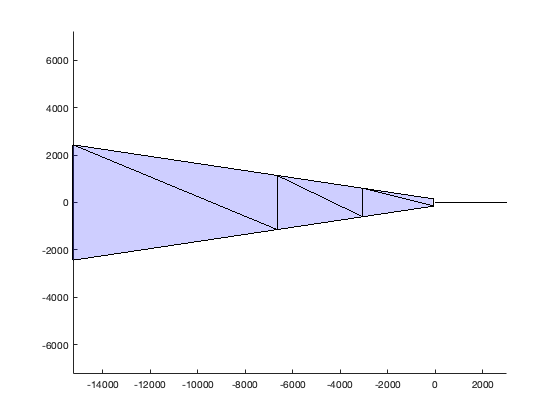



figure

hold on %tener dos O MAS graficas en mismos ejes
plot(Figurapista,'FaceColor','black','FaceAlpha',1); %plot de pista

plot(FiguraAprox,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox

plot(FiguraAprox2,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox


plot(FiguraAprox3,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox

hold off